# Testing Sensitivity Formula for the sAIF Controller

## Fixed Point Computation

clear
ComputeFP = @ComputeFP_rAIF_BirthDeath;

## Parameters

mu = 10;
theta = 0.4;
delta = 0.1;
eta = 3;
alpha = 20;
kappa = 1;
gamma_1 = 0.1;
Delta = 0.1;

## Numerical Computation of the Sensitivity

Parameters.mu = mu;
Parameters.theta = theta;
Parameters.delta = delta;
Parameters.eta = eta;
Parameters.alpha = alpha;
Parameters.kappa = kappa;
Parameters.gamma_1 = gamma_1 + Delta;

N = 100;
epsilon_vector = logspace(-5, -1, N);
Sensitivity_Numerical = zeros(N,1);
Output_Index = 1;
FP_0 = ComputeFP(Parameters);
for i = 1 : length(epsilon_vector)
    Parameters.gamma_1 = gamma_1 + Delta + epsilon_vector(i);
    FP_epsilon = ComputeFP(Parameters);
    Sensitivity_Numerical(i) = (FP_epsilon(Output_Index) - FP_0(Output_Index)) / epsilon_vector(i);
end
Sensitivity_Numerical = abs(Sensitivity_Numerical);

## Analytic Calculation of the Sensitivity

x_L = FP_0(Output_Index);
g = ((gamma_1+Delta)*kappa*x_L)/(alpha - (gamma_1+Delta)*x_L);
dgdx = (alpha*kappa*(Delta + gamma_1))/(Delta*x_L - alpha + gamma_1*x_L)^2;
dgdDelta = (alpha*kappa*x_L)/(Delta*x_L - alpha + gamma_1*x_L)^2;
Sensitivity_Analytical = abs(dgdDelta) / (abs(dgdx) + eta*theta*g / (delta*(eta*g + delta) - eta*(mu - theta*x_L - delta*g)) );

## Plot Results

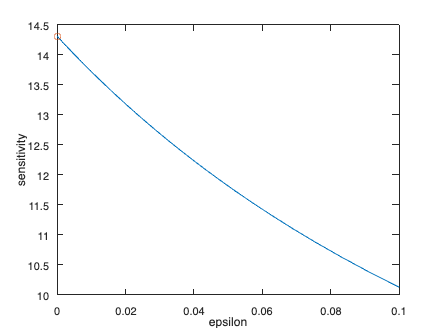

plot(epsilon_vector, Sensitivity_Numerical);
hold on
plot(0, Sensitivity_Analytical, 'o');
xlabel('epsilon');
ylabel('sensitivity')